# **From recording to results**

This is Shiqi'analysis on its recording. And the code is based on jinyouZou's work

**loda the data     **          

% clear all existed variables
clear
load liao-r1-07-Apr-2024-18-24.mat
true_label = dSigns;
record = reports;
Ntrial = 50;

**probability plot  **   

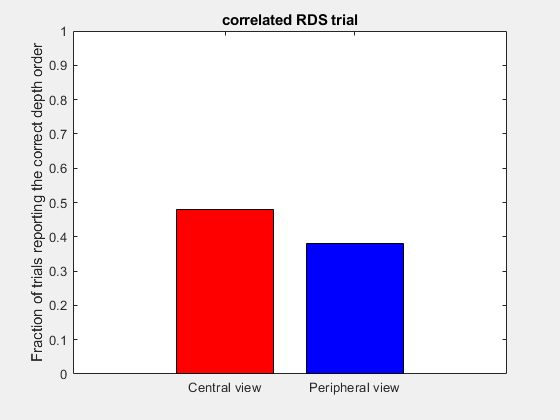

% correlated RDS
itypesRDSCorrelation = 1;
% central
true_label_correlated_RDS_central = squeeze(true_label(1, itypesRDSCorrelation, :, :));
record_correlated_RDS_central = squeeze(record(1, itypesRDSCorrelation, :, :));
correct_correlated_RDS_central = true_label_correlated_RDS_central == record_correlated_RDS_central;
probability_correlated_RDS_correct_central = sum(correct_correlated_RDS_central)/Ntrial;

% peripheral
true_label_correlated_RDS_peripheral = squeeze(true_label(2, itypesRDSCorrelation, :, :));
record_correlated_RDS_peripheral = squeeze(record(2, itypesRDSCorrelation, :, :));
correct_correlated_RDS_peripheral = true_label_correlated_RDS_peripheral == record_correlated_RDS_peripheral;
probability_correlated_RDS_correct_peripheral = sum(correct_correlated_RDS_peripheral)/Ntrial;

% plot probability
figure('visible','on');
X = [probability_correlated_RDS_correct_central probability_correlated_RDS_correct_peripheral ];
hold on
color_matrix = [1,0.0,0.0;0,0.0,1];         
for i = 1:2
    b = bar(i,X(i),0.75,'stacked');  
    set(b(1),'facecolor',color_matrix(i,:))
end
box on
Xlabel = {'Central view', 'Peripheral view'};
set(gca,'XTick',[1 2]);
set(gca,'XTickLabel',Xlabel);
set(gca,'YLim',[0.0 1]);
ylabel('Fraction of trials reporting the correct depth order') 
set(gca,'FontSize',10,'Fontname', 'Arial');
title('correlated RDS trial')
saveas(gcf,'fraction correlated_RDS_trial.png')

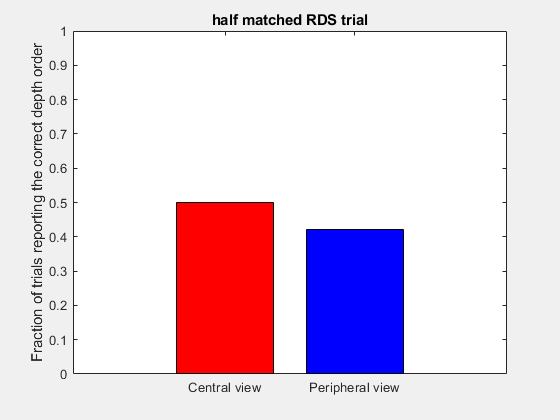

% half-matched RDS
itypesRDSCorrelation = 2;
% central
true_label_half_matched_RDS_central = squeeze(true_label(1, itypesRDSCorrelation, :, :));
record_half_matched_RDS_central = squeeze(record(1, itypesRDSCorrelation, :, :));
correct_half_matched_RDS_central = true_label_half_matched_RDS_central == record_half_matched_RDS_central;
probability_half_matched_RDS_correct_central = sum(correct_half_matched_RDS_central)/Ntrial;

% peripheral
true_label_half_matched_RDS_peripheral = squeeze(true_label(2, itypesRDSCorrelation, :, :));
record_half_matched_RDS_peripheral = squeeze(record(2, itypesRDSCorrelation, :, :));
correct_half_matched_RDS_peripheral = true_label_half_matched_RDS_peripheral == record_half_matched_RDS_peripheral;
probability_half_matched_RDS_correct_peripheral = sum(correct_half_matched_RDS_peripheral)/Ntrial;

% plot probability
figure('visible','on');
X = [probability_half_matched_RDS_correct_central probability_half_matched_RDS_correct_peripheral ];
hold on
color_matrix = [1,0.0,0.0;0,0.0,1];         
for i = 1:2
    b = bar(i,X(i),0.75,'stacked');  
    set(b(1),'facecolor',color_matrix(i,:))
end
box on
Xlabel = {'Central view', 'Peripheral view'};
set(gca,'XTick',[1 2]);
set(gca,'XTickLabel',Xlabel);
set(gca,'YLim',[0.0 1]);
ylabel('Fraction of trials reporting the correct depth order') 
set(gca,'FontSize',10,'Fontname', 'Arial');
title('half matched RDS trial')
saveas(gcf,'fraction half matched RDS trial.png')

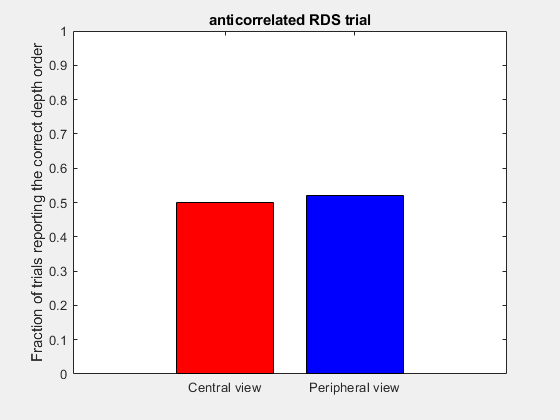

% anti-correlated RDS
itypesRDSCorrelation = 3;
% central
true_label_anticorrelated_RDS_central = squeeze(true_label(1, itypesRDSCorrelation, :, :));
record_anticorrelated_RDS_central = squeeze(record(1, itypesRDSCorrelation, :, :));
correct_anticorrelated_RDS_central = true_label_anticorrelated_RDS_central == record_anticorrelated_RDS_central;
probability_anticorrelated_RDS_correct_central = sum(correct_anticorrelated_RDS_central)/Ntrial;

% peripheral
true_label_anticorrelated_RDS_peripheral = squeeze(true_label(2, itypesRDSCorrelation, :, :));
record_anticorrelated_RDS_peripheral = squeeze(record(2, itypesRDSCorrelation, :, :));
correct_anticorrelated_RDS_peripheral = true_label_anticorrelated_RDS_peripheral == record_anticorrelated_RDS_peripheral;
probability_anticorrelated_RDS_correct_peripheral = sum(correct_anticorrelated_RDS_peripheral)/Ntrial;

% plot probability
figure('visible','on');
X = [probability_anticorrelated_RDS_correct_central probability_anticorrelated_RDS_correct_peripheral ];
hold on
color_matrix = [1,0.0,0.0;0,0.0,1];         
for i = 1:2
    b = bar(i,X(i),0.75,'stacked');  
    set(b(1),'facecolor',color_matrix(i,:))
end
box on
Xlabel = {'Central view', 'Peripheral view'};
set(gca,'XTick',[1 2]);
set(gca,'XTickLabel',Xlabel);
set(gca,'YLim',[0.0 1]);
ylabel('Fraction of trials reporting the correct depth order') 
set(gca,'FontSize',10,'Fontname', 'Arial');
title('anticorrelated RDS trial')
saveas(gcf,'fraction anticorrelated RDS.png')

**z-test (we use Two-Sample t -Test using the default siginificant level 0.05)**

correlated RDS

% correlated RDS
[h p ci stats]= ttest2(correct_correlated_RDS_central, correct_correlated_RDS_peripheral)

h = 0

p = 0.3174

ci =    -0.0975
    0.2975


stats = struct with fields:
    tstat: 1.0049
       df: 98
       sd: 0.4975


we cannot reject the null hypothesis as it has a probability of 0.3174 to happen. So that two trail recordings are not siginificantly different.

% half-matched RDS
[h p ci stats]= ttest2(correct_half_matched_RDS_central , correct_half_matched_RDS_peripheral)

h = 0

p = 0.4273

ci =    -0.1192
    0.2792


stats = struct with fields:
    tstat: 0.7971
       df: 98
       sd: 0.5018


we cannot reject the null hypothesis as it has a probability of 0.4273 to happen. So that two trail recordings are not siginificantly different.

% anti-correlated RDS
[h p ci stats]= ttest2(correct_anticorrelated_RDS_central , correct_anticorrelated_RDS_peripheral)

h = 0

p = 0.8434

ci =    -0.2204
    0.1804


stats = struct with fields:
    tstat: -0.1981
       df: 98
       sd: 0.5049


we cannot reject the null hypothesis as it has a probability of 0.8434 to happen. So that two trail recordings are not siginificantly different.

## Conclusion: the fraction of trials reporting the correct depth order for this subejct is not siginificant different in central viewing and peripheral viewing. 

Discussion: I think I don't get the point how to distinguish whether the central disk is in front of or behind the surrounding ring. I should take the practice trials:(